Fundamentos de control                                                                                                                                                                                                       

# Introducción a MATLAB

## Scripts, bucles e instrucciones condicionales

Hasta el momento hemos venido trabajando con **scripts vivos** que según MATLAB pueden definirse como: 

*"Archivos de programa que contienen código, salidas y texto con formato, y conviven en un solo entorno interactivo conocido como Live Editor. En los scripts en vivo, puede escribir código y ver las salidas y las gráficas generadas junto con el código que las produjo. Añada texto con formato, imágenes, hipervínculos y ecuaciones para crear una narrativa interactiva que puede compartir con otros."*

Esta manera de trabajar con MATLAB es bastante reciente, sin embargo, existe un enfoque más tradicional, que aún sigue siendo el adecuado cuando se necesita definir funciones complejas que alargarían en exceso los scripts vivos: los **archivos de comando** o **scripts** a secas.

En este cuaderno también vamos a ver unos commandos que nos permiten controlar el flujo de nuestros scripts: los **bucles** y las **instrucciones condicionales**.

## 1. Archivos de Comandos

Los archivos de comandos (archivos *script*) almacenan secuencias de sentencias. Se utilizan para llevar a cabo operaciones que involucran a múltiples sentencias, con objeto de evitar que cuando exista un error en alguna de ellas haya que reescribir y reejecutar todas las que le siguen. Asimismo, este tipo de archivos se puede utilizar simplemente para almacenar una secuencia de sentencias para la que se prevé una futura reutilización. Otro importante uso de los *script *es el de la definición de funciones. Por ejemplo, los comandos que hemos visto están definidos en este tipo de ficheros. 

La siguiente imagen muestra un ejemplo de un script que para un cierto vector `v` calcula su media y su desviación típica:

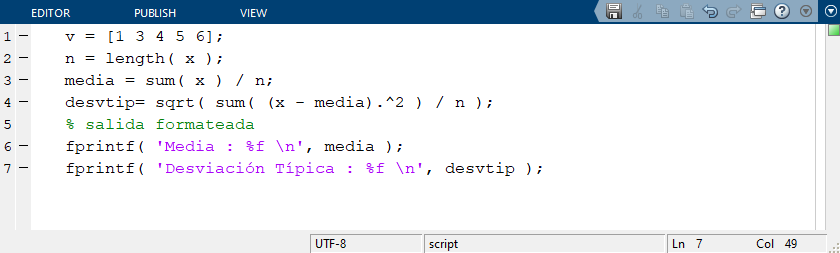

Mientras que la siguiente ilustra una función (comando) denominada `desv` que permite ejecutar el mismo código con distintos vectores de entrada:

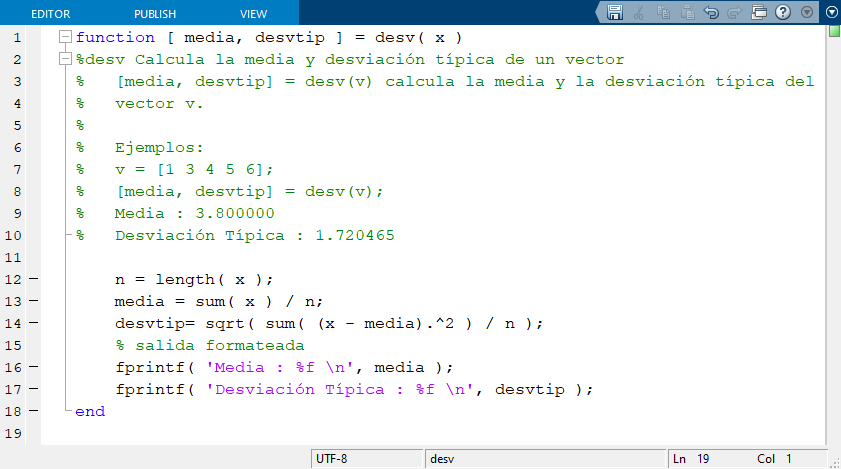

Los archivos de comandos tienen una extensión '.m' y pueden crearse en el editor que incorpora el entorno de MATLAB ('Home/New script' o 'Ctrl+N'). Las líneas de comentarios ubicadas por delante de la primera línea de programa de un archivo de comandos se muestran en la ventana de comandos de Matlab cuando en ésta se ejecuta el comando `help` seguido del nombre del archivo de comandos (excluyendo su extensión). 

Un archivo de comandos puede ejecutarse de distintas formas:

- o bien desde la ventana de comandos (escribiendo una sentencia con el nombre del fichero sin extensión), 

- directamente desde el editor del entorno de Matlab,

- o en una celda de código de un script vivo.

Para que dicha ejecución sea viable, el directorio en el que el que está almacenado el archivo de comandos considerado debe estar incluido en la lista de caminos de búsqueda de MATLAB ('Home/Set path'), el cual incluye el directorio de trabajo actual. Básicamente con esto nos aseguramos de que MATLAB conoce su existencia.

## `2. Bucles`

### `2.1 For`

El bucle por excelencia. Una instrucción `for` se repite un número especifico de veces, realizando un seguimiento de cada iteración con una variable en aumento. Su sintaxis es la siguiente:

`for ``index`` = ``values`

   `statements`

`end`

El siguiente código a ejecutar muesta un ejemplo en el que un bucle `for` recorre ciertas posiciones de un vector y suma sus elementos:

x = [1 2 1 2 1 2];
suma = 0;
for i=3:5
    suma = suma + x(i);
    disp(suma)
end

     1

     3

     4



Un bucle puede terminar bien sea por haber alcanzado el último valor de la variable en aumento a comprobar, o bien por la ejecución de la instrucción `break`. Por ejemplo:

suma = 0;
for i=3:5
    suma = suma + x(i);
    disp(suma)
    if i == 4
        break
    end
end

     1

     3



Por último, también podemos saltar a la siguiente iteración del bucle con el comando `continue`. Ejemplo:

suma = 0;
for i=3:5
    if i == 4
        continue
    end
    suma = suma + x(i);
    disp(suma)
end

     1

     2



**Tarea 1:** Define un vector fila de números aleatorios (generados a partir de una distribución de probablidad normal gaussiana) v con 10 elementos e implementa un bucle `for` que sume los que se encuentren en el rango de posiciones $\left\lbrack 2,7\right\rbrack$, mostrando el valor de la suma una vez concluido el bucle.

% Tu código aquí 
v = randn(1,10)

v =    -0.7342   -0.0308    0.2323    0.4264   -0.3728   -0.2365    2.0237   -2.2584    2.2294    0.3376


sum = 0;
for i=1:10
    if i >= 2 
        if  i <= 7
        sum = sum + v(1,i)
        end 
    end 
    disp(sum)
    disp(i)
end 

     0



     1



sum = -0.0308

   -0.0308



     2



sum = 0.2015

    0.2015



     3



sum = 0.6279

    0.6279



     4



sum = 0.2551

    0.2551



     5



sum = 0.0187

    0.0187



     6



sum = 2.0423

    2.0423



     7



    2.0423



     8



    2.0423



     9



    2.0423



    10



### `2.2 While`

La otra joya de la corona a nivel de bucle de control es el bucle `while`. Este bucle continúa realizando una serie de instrucciones mientras que la expressión que evalúa sea cierta. Su sintaxis es:

`while ``expression`

    `statements`

`end`

Un ejemplo de su uso:

i = 3;
suma = 0;
while i < 6
    suma = suma + x(i);
    disp(suma)
    i = i+1;
end

De igual modo que con el bucle `for`, usando `while` también se puede salir de dicho bucle con el comando `break`, o saltar a la siguiente iteración con `continue`.

## `3. Instrucciones condicionales`

### `3.1 Si yo tuviera... (if)`

Volvemos a encontrarnos con una instrucción popular: `if`. Esta instrucción condicional nos permite ejecutar una serie de instrucciones cuando una cierta condición es verdadera. En MATLAB una expresión es verdadera cuando su resultado no está vacío y contiene solo elementos no nulos (numéricos reales o lógicos). De lo contrario, la expresión es falsa.

Su sintaxis es:

`if ``expression`

    `statements`

`elseif ``expression`

    `statements`

`else`

    `statements`

`end`

Los bloques `elseif` y `else` son opcionales, y permiten indicar que ocurre si no se cumple la primera condición condicional pero sí una segunda (o un número de `n `de condiciones subsecuentes) y que ejecutar en cualquier otro caso, respectivamente.

Veamos un ejemplo del uso de `if` dentro de un bucle `for` que sólo suma los elementos en una posición par de un vector:

x = [1,2,1,2,1,2,1,2];
suma = 0;
n = length(x);
for i = 1:n
    if mod(i,2)
        suma = suma + x(i);
        disp(suma)
    end
end

**Tarea 2:** Usar el bucle `for` y la instrucción `if` para, una vez definido un vector v que contenga valores tanto negativos como positivos (definidor por ti), sume sólo los elementos positivos del vector. Muestra el resultado de la suma al salir del bucle.

% Tu código aquí 
v = [-3 -2 -1 0 1  5 10 20]

v =     -3    -2    -1     0     1     5    10    20


tam = 8;
sum = 0;

for i= 1:tam
    if v(i)>0 
        sum = sum + v(i)
    end
end

sum = 1

sum = 6

sum = 16

sum = 36

disp(sum)

    36



disp(i)

     8



### 3.2 El caso (switch)

Y concluímos nuestro repaso a las instrucciones condicionales de MATLAB con la sentencia switch, la cual permite evaluar una condición y ejecutar uno de varios grupos de instrucciones. Su sintaxis es:

`switch ``switch_expression`

`   case ``case_expression`

      `statements`

`   case ``case_expression`

      `statements`

`    ...`

`   otherwise`

      `statements`

`end`

El siguiente código a ejecutar muestra un ejemplo de su uso, donde se nos va a pedir que introduzcamos un número y se va a ejecutar un caso distinto en función de este:

n = input('Enter a number: ');

switch n
    case -1
        disp('negative one')
    case 0
        disp('zero')
    case 1
        disp('positive one')
    otherwise
        disp('other value')
end